clear

# Reading in the data

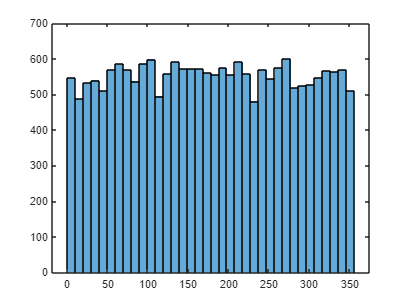

% ERA5 data
dur_era = (readmatrix("ERA5_dur.csv")/4)';
avg_lat_era = readmatrix("ERA5_avg_lat.csv")';
avg_lon_era = readmatrix("ERA5_avg_lon.csv")';

% 0-27C control data
[~, ~, gen_lat_ctr, gen_lon_ctr, avg_lat_ctr, avg_lon_ctr, end_lat_ctr, end_lon_ctr, dur_ctr, ~] = rcm2stats("AQ_SST0-27_Rows_Cols.csv");
[u_ctr,v_ctr,z_ctr,za_ctr,T_ctr,Ta_ctr,rv_ctr,div_ctr,om_ctr,eke_ctr,kfc_ctr,afc_ctr,brc_ctr,brt_ctr,vt1_ctr,vt2_ctr,ws_ctr,xlon,ylat,plevs] = comp_data("AQ_SST0-27","comp.nc");

% 15-27C mid data
[~, ~, gen_lat_mid, gen_lon_mid, avg_lat_mid, avg_lon_mid, end_lat_mid, end_lon_mid, dur_mid, ~] = rcm2stats("AQ_SST15-27_Rows_Cols.csv");
[u_mid,v_mid,z_mid,za_mid,T_mid,Ta_mid,rv_mid,div_mid,om_mid,eke_mid,kfc_mid,afc_mid,brc_mid,brt_mid,vt1_mid,vt2_mid,ws_mid,~,~,~] = comp_data("AQ_SST15-27","comp.nc");

% 20-27C hot data
[rws_hot, cls_hot, gen_lat_hot, gen_lon_hot, avg_lat_hot, avg_lon_hot, end_lat_hot, end_lon_hot, dur_hot, ~] = rcm2stats("AQ_SST20-27_Rows_Cols.csv");
[u_hot,v_hot,z_hot,za_hot,T_hot,Ta_hot,rv_hot,div_hot,om_hot,eke_hot,kfc_hot,afc_hot,brc_hot,brt_hot,vt1_hot,vt2_hot,ws_hot,~,~,~] = comp_data("AQ_SST20-27","comp.nc");

figure;
histogram(gen_lon_ctr,36)

% xlim([0 20])

function [rws, cls, gen_lat, gen_lon, avg_lat, avg_lon, end_lat, end_lon, dur, event_idx] = rcm2stats(rows_cols_fn)
    
    rcm = readmatrix(rows_cols_fn);
    rws = rcm(:,1:2:end);
    cls = rcm(:,2:2:end);
    event_idx = rot90(1:1:size(rws,2));

    for i = 1:size(rws,2)
        tmp_rw = nonzeros(rws(:,i));
        tmp_cl = nonzeros(cls(:,i));
    
        rw_log = cat(1,abs(tmp_rw(1:end-1)-tmp_rw(2:end))>10,false);
        cl_log = cat(1,abs(tmp_cl(1:end-1)-tmp_cl(2:end))>10,false);
    
        tmp_rw(rw_log) = floor(mean(tmp_rw(~rw_log)));
        tmp_cl(cl_log) = floor(mean(tmp_cl(~cl_log)));
    
        rws(1:length(tmp_rw),i) = tmp_rw;
        cls(1:length(tmp_cl),i) = tmp_cl;    
    end

    rws = rws(:,cls(1,:)>=3 & cls(1,:)<=285);
    cls = cls(:,cls(1,:)>=3 & cls(1,:)<=285);

    gen_rws = rws(1,:);
    gen_cls = cls(1,:);

    avg_rws = zeros(size(gen_rws));
    avg_cls = zeros(size(gen_cls));

    end_rws = zeros(size(gen_rws));
    end_cls = zeros(size(gen_rws));

    dur = zeros(size(avg_cls));

    num_evs = length(avg_cls);

    for i = 1:num_evs
        tmp_rw = nonzeros(rws(:,i));
        tmp_cl = nonzeros(cls(:,i));

        dur(i) = length(tmp_rw);

        avg_rws(i) = mean(tmp_rw);
        avg_cls(i) = mean(tmp_cl);

        end_rws(i) = tmp_rw(end);
        end_cls(i) = tmp_cl(end);
    end

    dur = dur/4;

    lats = linspace(0,90,96);
    lons = linspace(0,359,288);

    gen_lat = lats(gen_rws);
    gen_lon = lons(gen_cls);

    avg_lat = lats(round(avg_rws));
    avg_lon = lons(round(avg_cls));

    end_lat = lats(round(end_rws));
    end_lon = lons(round(end_cls));

    % val_ids = find(gen_lon>=3.75 & gen_lon<=356.25);
    % gen_lat = gen_lat(val_ids);
    % gen_lon = gen_lon(val_ids);
    % avg_lat = avg_lat(val_ids);
    % avg_lon = avg_lon(val_ids);
    % end_lat = end_lat(val_ids);
    % end_lon = end_lon(val_ids);
end

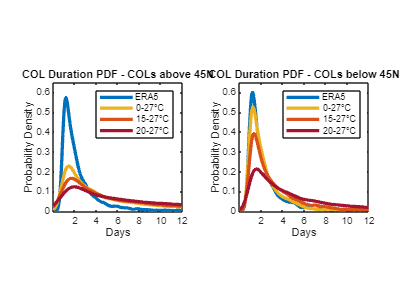

% Duration and Lat Relationship
dur_g45_era = dur_era(avg_lat_era>=45);
dur_l45_era = dur_era(avg_lat_era<45);

dur_g45_ctr = dur_ctr(avg_lat_ctr>=45);
dur_l45_ctr = dur_ctr(avg_lat_ctr<45);

dur_g45_mid = dur_mid(avg_lat_mid>=45);
dur_l45_mid = dur_mid(avg_lat_mid<45);

dur_g45_hot = dur_hot(avg_lat_hot>=45);
dur_l45_hot = dur_hot(avg_lat_hot<45);

x = 0:0.1:90;
blue = [0 0.4470 0.7410];
yellow = [0.9290 0.6940 0.1250];
orange = [0.8500 0.3250 0.0980];
red = [0.6350 0.0780 0.1840];
lw = 3;

pd_g45_era = fitdist(dur_g45_era','Kernel','Kernel','normal');
pd_g45_ctr = fitdist(dur_g45_ctr','Kernel','Kernel','normal');
pd_g45_mid = fitdist(dur_g45_mid','Kernel','Kernel','normal');
pd_g45_hot = fitdist(dur_g45_hot','Kernel','Kernel','normal');

pd_l45_era = fitdist(dur_l45_era','Kernel','Kernel','normal');
pd_l45_ctr = fitdist(dur_l45_ctr','Kernel','Kernel','normal');
pd_l45_mid = fitdist(dur_l45_mid','Kernel','Kernel','normal');
pd_l45_hot = fitdist(dur_l45_hot','Kernel','Kernel','normal');

pdf_g45_era = pdf(pd_g45_era,x);
pdf_g45_ctr = pdf(pd_g45_ctr,x);
pdf_g45_mid = pdf(pd_g45_mid,x);
pdf_g45_hot = pdf(pd_g45_hot,x);

cdf_g45_era = cdf(pd_g45_era,x);
cdf_g45_ctr = cdf(pd_g45_ctr,x);
cdf_g45_mid = cdf(pd_g45_mid,x);
cdf_g45_hot = cdf(pd_g45_hot,x);

pdf_l45_era = pdf(pd_l45_era,x);
pdf_l45_ctr = pdf(pd_l45_ctr,x);
pdf_l45_mid = pdf(pd_l45_mid,x);
pdf_l45_hot = pdf(pd_l45_hot,x);

cdf_l45_era = cdf(pd_l45_era,x);
cdf_l45_ctr = cdf(pd_l45_ctr,x);
cdf_l45_mid = cdf(pd_l45_mid,x);
cdf_l45_hot = cdf(pd_l45_hot,x);

figure;
tiledlayout(1,2);
nexttile;
plot(x,pdf_g45_era,"Color",blue,"LineWidth",lw)
hold on
plot(x,pdf_g45_ctr,"Color",yellow,"LineWidth",lw)
plot(x,pdf_g45_mid,"Color",orange,"LineWidth",lw)
plot(x,pdf_g45_hot,"Color",red,"LineWidth",lw)
title("COL Duration PDF - COLs above 45N")
xlabel("Days")
xlim([0.01 12])
ylim([0 0.65])
ylabel("Probability Density")
legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","northeast")
pbaspect([1 1 1])

nexttile;
plot(x,pdf_l45_era,"Color",blue,"LineWidth",lw)
hold on
plot(x,pdf_l45_ctr,"Color",yellow,"LineWidth",lw)
plot(x,pdf_l45_mid,"Color",orange,"LineWidth",lw)
plot(x,pdf_l45_hot,"Color",red,"LineWidth",lw)
title("COL Duration PDF - COLs below 45N")
xlabel("Days")
xlim([0.01 12])
ylim([0 0.65])
ylabel("Probability Density")
legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","northeast")
pbaspect([1 1 1])

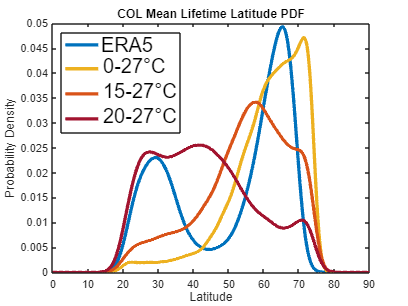

% % Mean Lifetime Location CDF / PDF figures
x = 0:0.1:90;
blue = [0 0.4470 0.7410];
yellow = [0.9290 0.6940 0.1250];
orange = [0.8500 0.3250 0.0980];
red = [0.6350 0.0780 0.1840];
lw = 3;

pd_era = fitdist(avg_lat_era','Kernel','Kernel','normal');
pd_ctr = fitdist(avg_lat_ctr','Kernel','Kernel','normal');
pd_mid = fitdist(avg_lat_mid','Kernel','Kernel','normal');
pd_hot = fitdist(avg_lat_hot','Kernel','Kernel','normal');

pdf_era = pdf(pd_era,x);
pdf_ctr = pdf(pd_ctr,x);
pdf_mid = pdf(pd_mid,x);
pdf_hot = pdf(pd_hot,x);

cdf_era = cdf(pd_era,x);
cdf_ctr = cdf(pd_ctr,x);
cdf_mid = cdf(pd_mid,x);
cdf_hot = cdf(pd_hot,x);

figure; % PDF plot
plot(x,pdf_era,"Color",blue,"LineWidth",lw)
hold on
plot(x,pdf_ctr,"Color",yellow,"LineWidth",lw)
plot(x,pdf_mid,"Color",orange,"LineWidth",lw)
plot(x,pdf_hot,"Color",red,"LineWidth",lw)
title("COL Mean Lifetime Latitude PDF")
xlabel("Latitude")
xlim([0 90])
ylabel("Probability Density")
legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","northwest")
hLegend = findobj(gcf, 'Type', 'Legend');
set(hLegend, 'FontSize', 2 * get(hLegend, 'FontSize'));

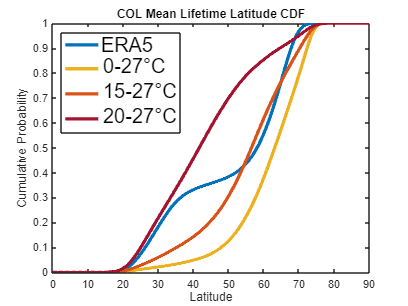


figure; % CDF plot
plot(x,cdf_era,"Color",blue,"LineWidth",lw)
hold on
plot(x,cdf_ctr,"Color",yellow,"LineWidth",lw)
plot(x,cdf_mid,"Color",orange,"LineWidth",lw)
plot(x,cdf_hot,"Color",red,"LineWidth",lw)
title("COL Mean Lifetime Latitude CDF")
xlabel("Latitude")
xlim([0 90])
ylabel("Cumulative Probability")
legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","northwest")
hLegend = findobj(gcf, 'Type', 'Legend');
set(hLegend, 'FontSize', 2 * get(hLegend, 'FontSize'));


% figure; % CDF plot Empirical
% cdfplot(avg_lat_era)
% hold on
% cdfplot(avg_lat_ctr)
% cdfplot(avg_lat_mid)
% cdfplot(avg_lat_hot)
% title("COL Mean Lifetime Latitude Empirical CDF")
% xlabel("Latitude")
% ylabel("Cumulative Probability Density")
% legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","northwest")

% % Duration PDF / CDF plots
x = 0:0.1:90

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


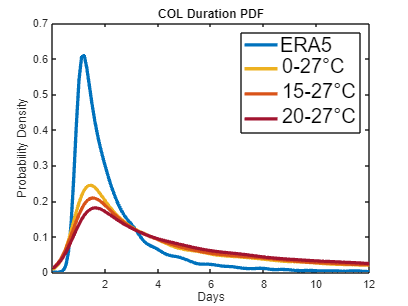

blue = [0 0.4470 0.7410];
yellow = [0.9290 0.6940 0.1250];
orange = [0.8500 0.3250 0.0980];
red = [0.6350 0.0780 0.1840];
lw = 3;

pd_era = fitdist(dur_era','Kernel','Kernel','normal');
pd_ctr = fitdist(dur_ctr','Kernel','Kernel','normal');
pd_mid = fitdist(dur_mid','Kernel','Kernel','normal');
pd_hot = fitdist(dur_hot','Kernel','Kernel','normal');

pdf_era = pdf(pd_era,x);
pdf_ctr = pdf(pd_ctr,x);
pdf_mid = pdf(pd_mid,x);
pdf_hot = pdf(pd_hot,x);

cdf_era = cdf(pd_era,x);
cdf_ctr = cdf(pd_ctr,x);
cdf_mid = cdf(pd_mid,x);
cdf_hot = cdf(pd_hot,x);

figure; % PDF plot
plot(x,pdf_era,"Color",blue,"LineWidth",lw)
hold on
plot(x,pdf_ctr,"Color",yellow,"LineWidth",lw)
plot(x,pdf_mid,"Color",orange,"LineWidth",lw)
plot(x,pdf_hot,"Color",red,"LineWidth",lw)
title("COL Duration PDF")
xlabel("Days")
xlim([0.01 12])
ylabel("Probability Density")
legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","northeast")
hLegend = findobj(gcf, 'Type', 'Legend');
set(hLegend, 'FontSize', 2 * get(hLegend, 'FontSize'));

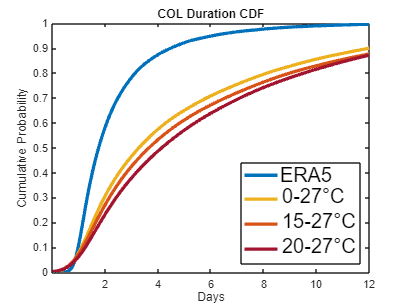


figure; % CDF plot
plot(x,cdf_era,"Color",blue,"LineWidth",lw)
hold on
plot(x,cdf_ctr,"Color",yellow,"LineWidth",lw)
plot(x,cdf_mid,"Color",orange,"LineWidth",lw)
plot(x,cdf_hot,"Color",red,"LineWidth",lw)
title("COL Duration CDF")
xlabel("Days")
xlim([0.01 12])
ylabel("Cumulative Probability")
legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","southeast")
hLegend = findobj(gcf, 'Type', 'Legend');
set(hLegend, 'FontSize', 2 * get(hLegend, 'FontSize'));


% figure; % CDF plot Empirical
% cdfplot(dur_era)
% hold on
% cdfplot(dur_ctr)
% cdfplot(dur_mid)
% cdfplot(dur_hot)
% title("COL Duration Empirical CDF")
% xlabel("Days")
% xlim([0 10])
% ylabel("Cumulative Probability Density")
% legend(["ERA5","0-27\circC","15-27\circC","20-27\circC"],"Location","northwest")

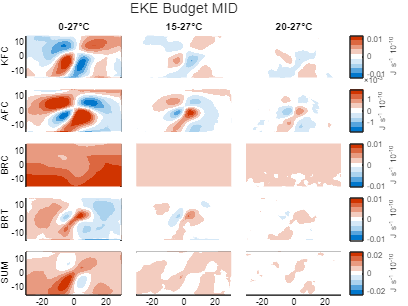

% % EKE Plots
ts = 3;
all_kfc = cat(4,kfc_ctr(:,:,:,ts),kfc_mid(:,:,:,ts),kfc_hot(:,:,:,ts));
all_afc = cat(4,afc_ctr(:,:,:,ts),afc_mid(:,:,:,ts),afc_hot(:,:,:,ts));
all_brc = cat(4,brc_ctr(:,:,:,ts),brc_mid(:,:,:,ts),brc_hot(:,:,:,ts));
all_brt = cat(4,brt_ctr(:,:,:,ts),brt_mid(:,:,:,ts),brt_hot(:,:,:,ts));

figure;
t1 = comp_eke(all_kfc,all_afc,all_brc,all_brt,xlon,ylat);
title(t1,"EKE Budget MID")

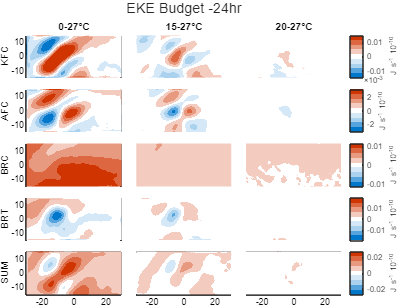


ts = 2;
all_kfc = cat(4,kfc_ctr(:,:,:,ts),kfc_mid(:,:,:,ts),kfc_hot(:,:,:,ts));
all_afc = cat(4,afc_ctr(:,:,:,ts),afc_mid(:,:,:,ts),afc_hot(:,:,:,ts));
all_brc = cat(4,brc_ctr(:,:,:,ts),brc_mid(:,:,:,ts),brc_hot(:,:,:,ts));
all_brt = cat(4,brt_ctr(:,:,:,ts),brt_mid(:,:,:,ts),brt_hot(:,:,:,ts));

figure;
t1 = comp_eke(all_kfc,all_afc,all_brc,all_brt,xlon,ylat);
title(t1,"EKE Budget -24hr")

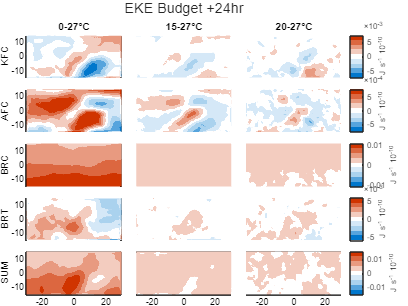


ts = 4;
all_kfc = cat(4,kfc_ctr(:,:,:,ts),kfc_mid(:,:,:,ts),kfc_hot(:,:,:,ts));
all_afc = cat(4,afc_ctr(:,:,:,ts),afc_mid(:,:,:,ts),afc_hot(:,:,:,ts));
all_brc = cat(4,brc_ctr(:,:,:,ts),brc_mid(:,:,:,ts),brc_hot(:,:,:,ts));
all_brt = cat(4,brt_ctr(:,:,:,ts),brt_mid(:,:,:,ts),brt_hot(:,:,:,ts));

figure;
t1 = comp_eke(all_kfc,all_afc,all_brc,all_brt,xlon,ylat);
title(t1,"EKE Budget +24hr")

% figure;
% t = tiledlayout(1,5);
% 
% nexttile;
% tmp = sum(kfc_ctr,3)
% tmp = tmp(:,:,1,3)
% % data = -dataa(:,:,1,1);
% % pcolor()



% for i = 1:Ncps % KFC row
%     h(i) = nexttile(t1);
%     dataa = sum(kfc,3);
%     data = -dataa(:,:,1,i);
%     pcolor(xlon,ylat,data)
%     shading interp
%     title(tstr(i))
%     set(gca, 'Color','none', 'XColor','none', 'YColor','none')
%     if i == 1
%         set(gca, 'Color','none', 'XColor','none', 'YColor','k')
%     end
% end
% set(h,'Colormap',cbf_div_chunk,'CLim',[-max(max(dataa(:,:,1,1))) max(max(dataa(:,:,1,1)))]);
% yl = ylabel(h(1),"KFC");
% yl.Color = 'k';
% c = colorbar(h(Ncps),"eastoutside");
% c.Label.String = 'J s^{-1} 10^{-10}';

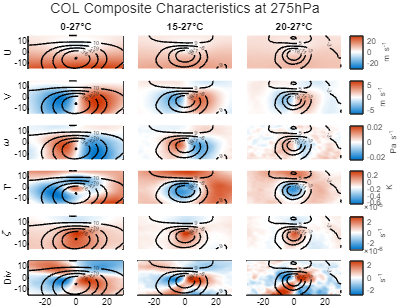

% % Composite Characteristics Plots
plev = 7;
zbuf = 0;
num_cons = 6;

u_all = combine_exps(u_ctr,u_mid,u_hot);
v_all = combine_exps(v_ctr,v_mid,v_hot);
za_all = combine_exps(za_ctr,za_mid,za_hot);
Ta_all = combine_exps(Ta_ctr,Ta_mid,Ta_hot);
rv_all = combine_exps(rv_ctr,rv_mid,rv_hot);
om_all = combine_exps(om_ctr,om_mid,om_hot);
div_all = combine_exps(div_ctr,div_mid,div_hot);

figure;
t2 = comp_plot(plev,zbuf,num_cons,u_all,v_all,za_all,Ta_all,rv_all,div_all,om_all,xlon,ylat);

% xlabel(t2,"Lon from Center")
% ylabel(t2,"Lat from Center")

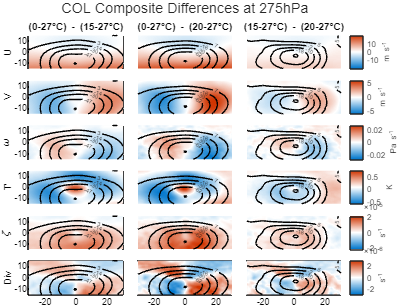

% % Composite Differences Plots
plev = 7;
zbuf = 0;
num_cons = 6;

udiff = cat(4,u_all(:,:,:,1)-u_all(:,:,:,2),u_all(:,:,:,1)-u_all(:,:,:,3),u_all(:,:,:,2)-u_all(:,:,:,3));
vdiff = cat(4,v_all(:,:,:,1)-v_all(:,:,:,2),v_all(:,:,:,1)-v_all(:,:,:,3),v_all(:,:,:,2)-v_all(:,:,:,3));
zadiff = cat(4,za_all(:,:,:,1)-za_all(:,:,:,2),za_all(:,:,:,1)-za_all(:,:,:,3),za_all(:,:,:,2)-za_all(:,:,:,3));
Tadiff = cat(4,Ta_all(:,:,:,1)-Ta_all(:,:,:,2),Ta_all(:,:,:,1)-Ta_all(:,:,:,3),Ta_all(:,:,:,2)-Ta_all(:,:,:,3));
rvdiff = cat(4,rv_all(:,:,:,1)-rv_all(:,:,:,2),rv_all(:,:,:,1)-rv_all(:,:,:,3),rv_all(:,:,:,2)-rv_all(:,:,:,3));
divdiff = cat(4,div_all(:,:,:,1)-div_all(:,:,:,2),div_all(:,:,:,1)-div_all(:,:,:,3),div_all(:,:,:,2)-div_all(:,:,:,3));
omdiff = cat(4,om_all(:,:,:,1)-om_all(:,:,:,2),om_all(:,:,:,1)-om_all(:,:,:,3),om_all(:,:,:,2)-om_all(:,:,:,3));

figure;
t3 = comp_diff_plot(plev,zbuf,num_cons,udiff,vdiff,zadiff,Tadiff,rvdiff,divdiff,omdiff,xlon,ylat);

% xlabel(t3,"Lon from Center")
% ylabel(t3,"Lat from Center")

function t1 = comp_diff_plot(plev,zbuf,num_cons,u,v,za,Ta,rv,div,om,xlon,ylat)
    zcons1 = round(linspace(min(min(za(:,:,plev,1)))+zbuf,max(max(za(:,:,plev,1)))-zbuf,num_cons));
    zcons2 = round(linspace(min(min(za(:,:,plev,2)))+zbuf,max(max(za(:,:,plev,2)))-zbuf,num_cons));
    zcons3 = round(linspace(min(min(za(:,:,plev,3)))+zbuf,max(max(za(:,:,plev,3)))-zbuf,num_cons));

    t1 = tiledlayout(6,3);
    t1.TileSpacing = 'tight';
    t1.Padding = 'tight';
    title(t1,"COL Composite Differences at 275hPa")
    Ncps = 3;
    h = zeros(Ncps,1);
    tstr = ["(0-27\circC) - (15-27\circC)","(0-27\circC) - (20-27\circC)","(15-27\circC) - (20-27\circC)"];
    con_data = squeeze(za(:,:,plev,:));
    cf_sz    = 5;
    for i = 1:Ncps % U
        h(i) = nexttile(t1);
        data = u(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons1,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons2,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons3,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        end
        hold off
        title(tstr(i))
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[-max(max(u(:,:,plev,2))) max(max(u(:,:,plev,2)))]);
    yl = ylabel(h(1),"U");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'm s^{-1}';

    for i = 1:Ncps % V
        h(i) = nexttile(t1);
        data = v(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons1,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons2,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons3,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[-max(max(v(:,:,plev,2))) max(max(v(:,:,plev,2)))]);
    yl = ylabel(h(1),"V");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'm s^{-1}';

    for i = 1:Ncps % omega
        h(i) = nexttile(t1);
        data = om(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons1,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons2,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons3,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[min(min(om(:,:,plev,2))) -min(min(om(:,:,plev,2)))]);
    yl = ylabel(h(1),"\omega");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'Pa s^{-1}';

    for i = 1:Ncps % T
        h(i) = nexttile(t1);
        data = Ta(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons1,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons2,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons3,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[min(min(Ta(:,:,plev,2))) max(max(Ta(:,:,plev,2)))]);
    yl = ylabel(h(1),"T'");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'K';

    for i = 1:Ncps % RV
        h(i) = nexttile(t1);
        data = rv(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons1,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons2,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons3,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[-max(max(rv(:,:,plev,2))) max(max(rv(:,:,plev,2)))]);
    yl = ylabel(h(1),"\zeta");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 's^{-1}';

    for i = 1:Ncps % divergence
        h(i) = nexttile(t1);
        data = div(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons1,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons2,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons3,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        end
        hold off
        set(gca, 'Color','none', 'XColor','k', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','k', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[min(min(div(:,:,plev,2))) -min(min(div(:,:,plev,2)))]);
    yl = ylabel(h(1),"Div");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 's^{-1}';
end

# ~ Functions ~

% function [rws, cls, gen_lat, gen_lon, avg_lat, avg_lon, end_lat, end_lon, dur, event_idx] = rcm2stats(rows_cols_fn)
% 
%     rcm = readmatrix(rows_cols_fn);
%     rws = rcm(:,1:2:end);
%     cls = rcm(:,2:2:end);
%     event_idx = rot90(1:1:size(rws,2));
% 
%     for i = 1:size(rws,2)
%         tmp_rw = nonzeros(rws(:,i));
%         tmp_cl = nonzeros(cls(:,i));
% 
%         rw_log = cat(1,abs(tmp_rw(1:end-1)-tmp_rw(2:end))>10,false);
%         cl_log = cat(1,abs(tmp_cl(1:end-1)-tmp_cl(2:end))>10,false);
% 
%         tmp_rw(rw_log) = floor(mean(tmp_rw(~rw_log)));
%         tmp_cl(cl_log) = floor(mean(tmp_cl(~cl_log)));
% 
%         rws(1:length(tmp_rw),i) = tmp_rw;
%         cls(1:length(tmp_cl),i) = tmp_cl;    
%     end
% 
%     gen_rws = rws(1,:);
%     gen_cls = cls(1,:);
% 
%     avg_rws = zeros(size(gen_rws));
%     avg_cls = zeros(size(gen_cls));
% 
%     end_rws = zeros(size(gen_rws));
%     end_cls = zeros(size(gen_rws));
% 
%     dur = zeros(size(avg_cls));
% 
%     num_evs = length(avg_cls);
% 
%     for i = 1:num_evs
%         tmp_rw = nonzeros(rws(:,i));
%         tmp_cl = nonzeros(cls(:,i));
% 
%         dur(i) = length(tmp_rw);
% 
%         avg_rws(i) = mean(tmp_rw);
%         avg_cls(i) = mean(tmp_cl);
% 
%         end_rws(i) = tmp_rw(end);
%         end_cls(i) = tmp_cl(end);
%     end
% 
%     dur = dur/4;
% 
%     lats = linspace(0,90,96);
%     lons = linspace(0,359,288);
% 
%     gen_lat = lats(gen_rws);
%     gen_lon = lons(gen_cls);
% 
%     avg_lat = lats(round(avg_rws));
%     avg_lon = lons(round(avg_cls));
% 
%     end_lat = lats(round(end_rws));
%     end_lon = lons(round(end_cls));
% end

function [u,v,z,za,T,Ta,rv,div,om,eke,kfc,afc,brc,brt,vt1,vt2,ws,xlon,ylat,plevs] = comp_data(prefix,suffix)    
    pre_48_fn = prefix + "_pre_48" + suffix;
    pre_24_fn = prefix + "_pre_24" + suffix;
    mid_ev_fn = prefix + "_ev_mid" + suffix;
    pst_24_fn = prefix + "_pst_24" + suffix;
    pst_48_fn = prefix + "_pst_48" + suffix;

    fns       = [pre_48_fn,pre_24_fn,mid_ev_fn,pst_24_fn,pst_48_fn];

    % Making some baseline vars
    Nlat = 31;
    Nlon = 61;
    Np   = 22;
    Ncps = 5;

    u   = zeros(Nlat,Nlon,Np,Ncps);
    v   = zeros(Nlat,Nlon,Np,Ncps);
    z   = zeros(Nlat,Nlon,Np,Ncps);
    za  = zeros(Nlat,Nlon,Np,Ncps);
    T   = zeros(Nlat,Nlon,Np,Ncps);
    Ta  = zeros(Nlat,Nlon,Np,Ncps);
    rv  = zeros(Nlat,Nlon,Np,Ncps);
    div = zeros(Nlat,Nlon,Np,Ncps);
    om  = zeros(Nlat,Nlon,Np,Ncps);

    eke = zeros(Nlat,Nlon,Np,Ncps);
    kfc = zeros(Nlat,Nlon,Np,Ncps);
    afc = zeros(Nlat,Nlon,Np,Ncps);
    brc = zeros(Nlat,Nlon,Np,Ncps);
    brt = zeros(Nlat,Nlon,Np,Ncps);
    vt1 = zeros(Nlat,Nlon,Np,Ncps);
    vt2 = zeros(Nlat,Nlon,Np,Ncps);

    for i = 1:Ncps
        u(:,:,:,i)   = ncread(fns(i),"U");
        v(:,:,:,i)   = ncread(fns(i),"V");
        z(:,:,:,i)   = ncread(fns(i),"Z3");
        za(:,:,:,i)  = ncread(fns(i),"Z3a");
        T(:,:,:,i)   = ncread(fns(i),"T");
        Ta(:,:,:,i)  = ncread(fns(i),"Ta");
        rv(:,:,:,i)  = ncread(fns(i),"RV");
        div(:,:,:,i) = ncread(fns(i),"DIV");
        om(:,:,:,i)  = ncread(fns(i),"OMEGA");

        eke(:,:,:,i) = ncread(fns(i),"EKE");
        kfc(:,:,:,i) = ncread(fns(i),"KFC");
        afc(:,:,:,i) = ncread(fns(i),"AFC");
        brc(:,:,:,i) = ncread(fns(i),"BRC");
        brt(:,:,:,i) = ncread(fns(i),"BRT");
        vt1(:,:,:,i) = ncread(fns(i),"VERT1");
        vt2(:,:,:,i) = ncread(fns(i),"VERT2");
    end
    ws = sqrt(u.^2 + v.^2);

    xlon  = -30:1:30;
    ylat  = -15:1:15;
    plevs = [103.3, 121.5, 143.0, 168.2, 197.9, 232.8, 273.9, 322.2, 379.1, 446.0, 524.7,...
             609.8, 691.4, 763.4, 820.9, 859.5, 887.0, 912.6, 936.2, 957.5, 976.3, 992.6];
end

function t1 = comp_eke(kfc,afc,brc,brt,xlon,ylat)
    t1 = tiledlayout(5,3);
    t1.TileSpacing = 'tight';
    t1.Padding = 'tight';
    Ncps = 3;
    h = zeros(Ncps,1);
    tstr = ["0-27\circC","15-27\circC","20-27\circC"];
    for i = 1:Ncps % KFC row
        h(i) = nexttile(t1);
        dataa = sum(kfc,3);
        data = -dataa(:,:,1,i);
        pcolor(xlon,ylat,data)
        shading interp
        title(tstr(i))
        set(gca, 'Color','none', 'XColor','none', 'YColor','none')
        if i == 1
            set(gca, 'Color','none', 'XColor','none', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div_chunk,'CLim',[-max(max(dataa(:,:,1,1))) max(max(dataa(:,:,1,1)))]);
    yl = ylabel(h(1),"KFC");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'J s^{-1} 10^{-10}';

    for i = 1:Ncps % AFC
        h(i) = nexttile(t1);
        dataa = sum(afc,3);
        data = -dataa(:,:,1,i);
        pcolor(xlon,ylat,data)
        shading interp
        set(gca, 'Color','none', 'XColor','none', 'YColor','none')
        if i == 1
            set(gca, 'Color','none', 'XColor','none', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div_chunk,'CLim',[-max(max(dataa(:,:,1,1))) max(max(dataa(:,:,1,1)))]);
    yl = ylabel(h(1),"AFC");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'J s^{-1} 10^{-10}';

    for i = 1:Ncps % BRC
        h(i) = nexttile(t1);
        dataa = sum(brc,3);
        data = -dataa(:,:,1,i);
        pcolor(xlon,ylat,data)
        shading interp
        set(gca, 'Color','none', 'XColor','none', 'YColor','none')
        if i == 1
            set(gca, 'Color','none', 'XColor','none', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div_chunk,'CLim',[min(min(dataa(:,:,1,1))) -min(min(dataa(:,:,1,1)))]);
    yl = ylabel(h(1),"BRC");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'J s^{-1} 10^{-10}';

    for i = 1:Ncps % BRT
        h(i) = nexttile(t1);
        dataa = sum(brt,3);
        data = -dataa(:,:,1,i);
        pcolor(xlon,ylat,data)
        shading interp
        set(gca, 'Color','none', 'XColor','none', 'YColor','none')
        if i == 1
            set(gca, 'Color','none', 'XColor','none', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div_chunk,'CLim',[-max(max(dataa(:,:,1,1))) max(max(dataa(:,:,1,1)))]);
    yl = ylabel(h(1),"BRT");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'J s^{-1} 10^{-10}';

    for i = 1:Ncps % SUM
        h(i) = nexttile(t1);
        dataa = sum(kfc,3) + sum(afc,3) + sum(brc,3) + sum(brt,3);
        data = -dataa(:,:,1,i);
        pcolor(xlon,ylat,data)
        shading interp
        set(gca, 'Color','none', 'XColor','k', 'YColor','none')
        if i == 1
            set(gca, 'Color','none', 'XColor','k', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div_chunk,'CLim',[min(min(dataa(:,:,1,1))) -min(min(dataa(:,:,1,1)))]);
    yl = ylabel(h(1),"SUM");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'J s^{-1} 10^{-10}';
end

function t1 = comp_plot(plev,zbuf,num_cons,u,v,za,Ta,rv,div,om,xlon,ylat)
    zcons_ctr = round(linspace(min(min(za(:,:,plev,1)))+zbuf,max(max(za(:,:,plev,1)))-zbuf,num_cons));
    zcons_mid = round(linspace(min(min(za(:,:,plev,2)))+zbuf,max(max(za(:,:,plev,2)))-zbuf,num_cons));
    zcons_hot = round(linspace(min(min(za(:,:,plev,3)))+zbuf,max(max(za(:,:,plev,3)))-zbuf,num_cons));

    t1 = tiledlayout(6,3);
    t1.TileSpacing = 'tight';
    t1.Padding = 'tight';
    title(t1,"COL Composite Characteristics at 275hPa")
    % subtitle(t1,"\Phi' Contours")
    Ncps = 3;
    h = zeros(Ncps,1);
    tstr = ["0-27\circC","15-27\circC","20-27\circC"];
    con_data = squeeze(za(:,:,plev,:));
    cf_sz    = 5;
    for i = 1:Ncps % U
        h(i) = nexttile(t1);
        data = u(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_ctr,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_mid,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_hot,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)            
        end
        hold off
        title(tstr(i))
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[-max(max(u(:,:,plev,1))) max(max(u(:,:,plev,1)))]);
    yl = ylabel(h(1),"U");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'm s^{-1}';

    for i = 1:Ncps % V
        h(i) = nexttile(t1);
        data = v(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_ctr,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_mid,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_hot,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)            
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[-max(max(v(:,:,plev,1))) max(max(v(:,:,plev,1)))]);
    yl = ylabel(h(1),"V");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'm s^{-1}';

    for i = 1:Ncps % omega
        h(i) = nexttile(t1);
        data = om(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_ctr,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_mid,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_hot,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)            
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end  
    end
    set(h,'Colormap',cbf_div,'CLim',[min(min(om(:,:,plev,1))) -min(min(om(:,:,plev,1)))]);
    yl = ylabel(h(1),"\omega");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'Pa s^{-1}';

    for i = 1:Ncps % T
        h(i) = nexttile(t1);
        data = Ta(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_ctr,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_mid,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_hot,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)            
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[min(min(Ta(:,:,plev,1))) max(max(Ta(:,:,plev,1)))]);
    yl = ylabel(h(1),"T'");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 'K';

    for i = 1:Ncps % RV
        h(i) = nexttile(t1);
        data = rv(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_ctr,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_mid,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_hot,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)            
        end
        hold off
        set(gca, 'Color','none', 'XColor','w', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','w', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[-max(max(rv(:,:,plev,1))) max(max(rv(:,:,plev,1)))]);
    yl = ylabel(h(1),"\zeta");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 's^{-1}';

    for i = 1:Ncps % divergence
        h(i) = nexttile(t1);
        data = div(:,:,plev,i);
        pcolor(xlon,ylat,data)
        shading interp
        hold on
        if i == 1
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_ctr,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)
        elseif i == 2
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_mid,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)  
        else
            [C,ch] = contour(xlon,ylat,con_data(:,:,i),zcons_hot,"EdgeColor","k");
            clabel(C,ch,'FontSize',cf_sz)            
        end
        hold off
        set(gca, 'Color','none', 'XColor','k', 'YColor','w')
        if i == 1
            set(gca, 'Color','none', 'XColor','k', 'YColor','k')
        end
    end
    set(h,'Colormap',cbf_div,'CLim',[min(min(div(:,:,plev,1))) -min(min(div(:,:,plev,1)))]);
    yl = ylabel(h(1),"Div");
    yl.Color = 'k';
    c = colorbar(h(Ncps),"eastoutside");
    c.Label.String = 's^{-1}';
end

function var_all = combine_exps(v1,v2,v3)
    var_all = cat(4,v1(:,:,:,3),v2(:,:,:,3),v3(:,:,:,3));
end